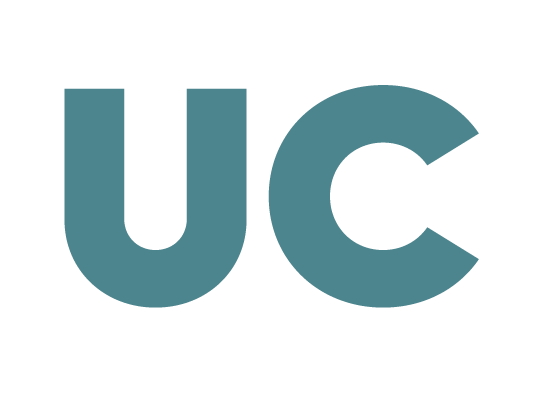

***Grado de Tecnologías de Telecomunicación***

**G282: Álgebra y Geometria**

# **Práctica 6: Espacios vectoriales (III)**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

format rat
clear all;

## 1. Formas de expresar subespacios vectoriales

Un subespacio vectorial puede ser definido y representado de diversas maneras, cada una con sus propias características y utilidades. Las principales formas son:

- **forma implícita**: un conjunto de ecuaciones no redundates que especifican las restricciones de los vectores del subespacio.

- **forma paramétrica**: expresión que nos permite obtener todos los vectores del subespacio dando valores a los parámetros.

- **base**: conjunto de vectores linealmente independientes cuyas combinaciones lineales nos permiten obtener cualquier vector del subespacio.

**Nota: **también podemos expresar el subespacio a partir de un sistema generador que no sea base, sin embargo un sistema generador tipo base es la forma más compacta, ya que tiene el mínimo número de vectores necesarios para describir completamente el subespacio. 

### 1.1 Paso de forma  implícita a paramétricas 

La forma implícita de un subespacio es un conjunto de ecuaciones que forman un sistema lineal homogéneo. Estas ecuaciones implícitas determinan las condiciones que deben cumplir los vectores de dicho subespacio. Para obtener la forma paramétrica de S debemos resolver el sistema.

Veamos un ejemplo. Sea $S$ un subespacio de $\mathbb{R}^4$ dado en su forma implícita, $S: \left.
x + y - z - t = 0 \atop
2x + 2y - z - t = 0
\right\} 
 \leftrightarrow
\left(\begin{array}{cccc}
     1 & 1 & -1 & -1\\  
     2 & 2 & -1 & -1\end{array}\right)
\left(\begin{array}{cccc}
    x\\ 
y\\
z\\
t \end{array}\right)
=\left(\begin{array}{cccc}
   0\\ 
0\\
0\\
0 \end{array}\right)$

Abamos de ver que para obtener una base del mismo bastará con resolver el sistema homogéneo que forman sus ecuaciones implícitas. Puesto que todos los subespacios de $\mathbb{R}^n$ deben contener al vector nulo, cualquier subespacio de $\mathbb{R}^n$ será siempre un sistema homogéneo y podremos resolverlo con la función `null.` 

coefImpS = [1 1 -1 -1; 2 2 -1 -1];  % matriz de coefs. del sistema homogéneo
baseS = null(coefImpS, 'rational')  % cada columna es un vector de la base de S

La función null nos devuelve vectores cuya combinación lineal es la solución general del sistema homogéneo. Es decir, en este ejemplo la solución general es: 


$$ S: \{ \alpha \left(\begin{array}{cccc}
    -1 \\  
   1\\  
    0\\  
     0\end{array}\right)
+\beta \left(\begin{array}{cccc}
    0 \\  
   0\\  
    -1\\  
1\end{array}\right)\} $$


Por tanto, la forma paramétrica que buscamos es $S=\lbrace (-\alpha, \alpha  -\beta, \beta,\beta): \alpha, \beta \in \mathbb{R} \rbrace$

### **1.2 Paso de la forma paramétrica de un subespacio a la implícita (implicitación)**

Sea $S$ un subespacio de $\mathbb{R}^4$ dado en su forma paramétrica, por ejemplo $S = \lbrace (\alpha, \alpha, \beta, \beta )=\alpha(1,1,0,0)+\beta(0,0,1,1): \alpha, \beta \in \mathbb{R}\rbrace$ cuya base está formada por los vectores $(1,1,0,0)
$ y $(0,0,1,1)$. Sabemos que cualquier vector de $S$ (y en particular los vectores de la base) verificarán las ecuaciones implícitas del subespacio, cuya forma general para subespacios de $\mathbb{R}^4$ será $ax + by + cz + dt  = 0$. Es decir, en este ejemplo debe cumplirse


$$\begin{array}{cccc}
a\cdot 1 + b\cdot 1 + c\cdot 0 + d \cdot 0  = 0 \\
a\cdot 0 + b \cdot 0 + c \cdot 1 + d \cdot 1  = 0 
\end{array}
 \leftrightarrow
\left(\begin{array}{cccc}
     1 & 1 & 0 &0\\  
    0 &0 & 1 &1\end{array}\right)
\left(\begin{array}{cccc}
    a\\ 
b\\
c\\
d \end{array}\right)
=\left(\begin{array}{cccc}
   0\\ 
0\\
0\\
0 \end{array}\right)$$


Por tanto, bastará con resolver el sistema homogéneo donde las incógnitas serán los coeficientes de las ecuaciones implícitas ($a,b,c \text{ y } d$ en este ejemplo), y cuya matriz de coeficientes estará formada por los vectores de la base (colocados en filas).

Resolvemos este sistema lineal homogéneo con la función `null`.    

baseS = [1 1 0 0; 0 0 1 1]';  % base de S (en columnas)
null(baseS', 'rational')      % matriz con los vectores de la base por columnas traspuesta 

La función `null` nos devuelve vectores cuya combinación lineal es la solución general del sistema homogéneo. Es decir, en este ejemplo la solución general es: 


$$ \left(\begin{array}{cccc}
    a \\  
   b\\  
    c\\  
     d\end{array}\right) = \alpha \left(\begin{array}{cccc}
    -1 \\  
   1\\  
    0\\  
     0\end{array}\right)
+\beta \left(\begin{array}{cccc}
    0 \\  
   0\\  
    -1\\  
1\end{array}\right)$$


Dando valores a los parámetros libres obtenemos las 2 ecuaciones implícitas del sistema. 


$$\text{Si } \alpha=1, \beta=0 \rightarrow (a,b,c,d)=(-1,1,0,0) \rightarrow-x+y=0 \\
\text{Si } \alpha=0, \beta=1 \rightarrow (a,b,c,d)=(0,0,-1,1) \rightarrow -z+t=0$$
 

La expresión del subespacio en implícitas será por tanto $S: \left.
-x + y= 0 \atop
-z + t  = 0
\right\} $

**Nota:** Resulta más conveniente para ver estas ecuaciones y guardar sus coeficientes transponer la matriz devuelta por `null`. De esta manera tendremos los coeficientes de las ecuaciones implícitas de S por filas:

coefImpS=null(baseS', 'rational')' % notar la trasposición para ver la disposición correcta de la matriz de coeficientes.


### **1.3 Obtención de una base de un subespacio**

Un subespacio además de por su forma paramétrica y su forma implícita también quedar representado por su base. A continuación veremos cómo obtener una base de un subespacio partiendo de su forma paramétrica o implícita.

#### **1.3.1 Base a partir de forma paramétrica.**

Si el subespacio viene dado por su forma paramétrica, la obtención de una base del subespacio es directa.  Por ejemplo, para el subespacio $S$ de $\mathbb{R}^5$: 


$$S = \lbrace (2\alpha + 3\beta \, ,  \,  2\beta - \gamma  \,  ,   \,  -3\alpha + \beta   \,  , \,  -\gamma ,  \, \beta)  : \alpha, \beta, \gamma \in \mathbb{R} \rbrace$$



$$S: \{ \alpha \left(\begin{array}{cccc}
    2 \\  
   0 \\  
    -3\\  
0\\
     0\end{array}\right)
+\beta \left(\begin{array}{cccc}
    3 \\  
   2\\  
    1\\  
0\\  
     1\end{array}\right)
+\gamma \left(\begin{array}{cccc}
    0 \\  
   -1\\  
    0\\  
-1\\  
     0\end{array}\right)
\}$$
 

Una base sería $\lbrace (2,0,-3,0,0), (3,2,1,0,1), (0,-1,0,-1,0) \rbrace$.

baseS = [2 0 -3 0 0; 3 2 1 0 1; 0 -1 0 -1 0]' ; % traspuesta para que sean vectores por columnas

***Nota******:*** *Como convenio, siempre que introduzcamos por teclado una base colocaremos los vectores que la componen en columnas.*

#### 1.3.2 Base a partir de forma implícita. 

Si, por el contrario, lo que se conoce del subespacio son sus ecuaciones implícitas, podemos obtener su forma paramétrica simplemente resolviendo el sistema lineal de ecuaciones. Puesto que todos los subespacios deben contener al vector cero, el sistema lineal será siempre homogéneo y podremos resolverlo con la función `null`. 

Por ejemplo, en el caso del subespacio $T$ de $\mathbb{R}^4$: 


$$T:\textstyle\left\{  \begin{array}{rcr}
			 x-y+2z +3t & = & 0\\ 
			 3x-2y+z-t & = & 0\\			
		 \end{array}\right. \, 
 \leftrightarrow \,
\left(\begin{array}{cccc}
     1 & -1 & 2 & 3\\  
     3 & -2 & 1 & -1\end{array}\right)
\left(\begin{array}{cccc}
    x\\ 
y\\
z\\
t \end{array}\right)
=\left(\begin{array}{cccc}
   0\\ 
0\\
0\\
0 \end{array}\right)$$


cuya matriz de coeficientes guardaremos en la variable `coefImpT`

coefImpT = [1 -1 2 3; 3 -2 1 -1];   % matriz de coefs. del sistema homogéneo
baseT = null(coefImpT, 'rational')  % con versiones anteriores de matlab poner "r" en vez de "rational"

La función `null` nos devuelve vectores cuya combinación lineal es la solución general del sistema homogéneo. Es decir, en este ejemplo la solución general es:


$$ S: \{ \lambda \left(\begin{array}{cccc}
    3 \\  
   5\\  
    1\\  
     0\end{array}\right)
+\beta \left(\begin{array}{cccc}
    7 \\  
   10\\  
    0\\  
1\end{array}\right)\} $$


Es decir, la función `null` nos devuelve directamente una base del subespacio $S:$$\{(3,4,1,0),(7,10,0,1)\}$. 

***Nota******:*** *Recuerda que la base obtenida no es única, sino que hay infinitas. Por ejemplo, otra posible base del ejemplo anterior sería {(10 15 1 1),(7 10 0 1)}*

## **2. Operaciones con subespacios**

### **2.1 Intersección de dos subespacios**

Sean $S$ y $T$ dos subespacios de $\mathbb{R}^4$ dados por sus ecuaciones implícita

                
$$S: \left.
x + y - z - t = 0 \atop
2x + 2y - z - t = 0
\right\} $$
                           
$$T: \left.
x - y = 0 \atop
z - t = 0
\right\} $$


El subespacio $S \cap T$está formado por los vectores que cumplen tanto las ecuaciones implicitas $S$ como las de $T$. Por lo que se calcula resolviendo el sistema formado por las ecuaciones de $S$ y las de $T$, ya que cualquier elemento de la intersección estará a la vez en $S$ y en $T$, y por tanto, verificará ambos conjuntos de ecuaciones simultáneamente.  


$$S\cap T:  \left. \begin{array}{cccc}
x + y - z - t = & 0 \\
2x + 2y - z - t =& 0\\
x - y =& 0 \\
z - t = &0 \\
\end{array}
\right\} $$


coefImpS = [1 1 -1 -1; 2 2 -1 -1] ;  % coefs. eqs. implícitas S
coefImpT = [1 -1 0 0 ; 0 0 1 -1]  ;  % coefs. eqs. implícitas T 

baseSinterT = null([coefImpS; coefImpT], 'rational')  % resuelvo el sistema homogéneo --> 




Puesto que la función `null` nos devuelve un vector vacío, el sistema sólo tiene la solución trivial. Por lo que el subespacio intersección de S y T está compuesto tan sólo por el vector nulo. $S \cap T=\{ (0,0,0,0\}$.Por tanto S y T están en suma directa, $dim(S \cap T)=0$ . 

**Nota: **Ojo al juntar las ecuaciones de ambos sistemas no siempre tenemos porqué obtener las ecuaciones implícitas de $S \cap T$, ya que las ecuaciones implícitas por definición deben ser no redundantes. Si queremos hallar las ecuaciones implícitas de $S \cap T$ debemos obtener un sistema escalonado equivalente y quedarnos con las ecuaciones que en él aparezcan (las filas de  ceros no nos dan ecuaciones, porque simplemente informan de que  0=0).

rref([coefImpS; coefImpT])

En este ejemplo vemos que el rango es igual al numero de ecuaciones y que por tanto no hay ecuaciones redundantes (ecuaciones que son C.L del resto). Por lo que las 4 ecuaciones forman las ecuaciones implícitas de $S \cap T$. El subespacio vectorial $S \cap T$ de $\mathbb{R}^4$ , tiene 4 ecuaciones implícitas y 0 parámetros libres, es decir, $dim(S \cap T)=0$.  (es decir, dim ($\mathbb{R}^4$) = 4 ecuaciones implícitas + 0 p.l).

### **2.2 Suma de dos subespacios**

Para calcular el subespacio $S+T$, obtendremos en primer lugar una base de $S$ y otra de $T$. A partir de ellas, es inmediato formar un sistema generador de $S+T$ (sólo habrá que unir ambas bases).

Sean $S$ y $T$ dos subespacios de $\mathbb{R}^4$ dados por sus ecuaciones implícitas (los mismos que en el apartado anterior):

                
$$S: \left.
x + y - z - t = 0 \atop
2x + 2y - z - t = 0
\right\} $$
                           
$$T: \left.
x - y = 0 \atop
z - t = 0
\right\} $$


baseS = null(coefImpS, 'r')  % base de S --> dim(S)=2
baseT = null(coefImpT, 'rational')  % base de T --> dim(T)=2
genST = [baseS baseT]  % sistema generador de S+T

Una vez tenemos un sistema generador de $S+T$, podemos extraer de él una base de $S+T$, sin más que tomar  los vectores necesarios para mantener el rango.  Es importante recordar que la dimensión de un espacio vectorial es igual al rango de los vectores de cualquier sistema generador del mismo. Veamos primero cual es la dimensión de S+T.

rank(genST)  % rango máximo --> sistema libre 

En este caso los 4 vectores del sistema generador son libres, luego forman una base de  $S+T$.

% Por tanto, genST será una base del subespacio suma (S+T), es decir:
baseST = genST  % dim(S+T)=4

Si nos fijamos en la fórmula de Grassmann $\textbf{dim(S+T)=dim(S)+dim(T)-dim(S $\cap$ T)}$, en este ejemplo al ser suma directa tenemos  $dim(S \cap T)=0$ . Por otra parte tanto la dimensión de S como la de T toman el valor 2, $dim(S)=dim(T)=2$ (ya que tanto S como T tienen 2 ecuaciones implícitas en $\mathbb{R}^4$). Por lo que  $dim(S+T)=4$, es decir la suma de S y T es todo $\mathbb{R}^4$. S y T son espacios suplementarios.

### **2.3 Búsqueda de espacios suplementarios **

El suplementario de un subespacio en$V$=$\mathbb{R}^5$, es aquel subespacio $T$ que cumple que: 


$$dim(S \cap T)=0 \quad
dim(S+T)=V$$
  

**Ejemplo**. Sea el subespacio de $\mathbb{R}^5$, dado por las siguientes ecuaciones en las variables *(x,y,z,t,r).*


$$S: \left.
-143x -54y -44r = 0 \atop
t = 0
\right\} $$
  

Para encontrar un subespacio suplementario de $S$ en $\mathbb{R}^5$, lo primero es hallar una base de $S$ (resolvemos el sistema):

coefImpS = [-143 -54 0 0 -44; 0 0 0 1 0];
baseS = null(coefImpS, 'rational')  % dim(S)=3
rank(baseS) % el subespacio S tiene rango 3 (dimensión 3). null siempre nos da vectores l.i.

Una vez tenemos una base de S, se trata de extender esta base añadiendo nuevos vectores que sean linealmente independientes de los anteriores hasta formar una base del espacio total, $\mathbb{R}^5$ en este caso. Puesto que la base de S tiene dimensión 3, sabemos que una base del espacio suplementario tendrá 2 vectores.

Podemos probar a añadir cualquier vector, por ejemplo, los de la base canónica de $\mathbb{R}^5$. Lo que tenemos que comprobar es que el vector añadido aumente el rango del conjunto.

rank([baseS, [1 0 0 0 0]'])  % ya tenemos el primer vector, tenemos 4 vectores l.i.

Comprobamos como el rango aumenta. Los 4 vectores son libres, nos falta encontrar otro vector libre. Probamos con otro de la base canónica por comodidad

rank([baseS, [1 0 0 0 0]', [0 1 0 0 0]'])  

[0 1 0 0 0]' este no nos sirve. Probamos con el siguiente:

rank([baseS, [1 0 0 0 0]', [0 0 0 1 0]'])  

Ahora sí, ya tenemos 5 vectores l.i que generan todo $\mathbb{R}^5$. Los tres primeros forman una base de S y los 2 añadidos una base de su suplementario en $\mathbb{R}^5$.

Los vectores que hemos añadido a los de la base de $S$ forman una base del suplementario de S en  $\mathbb{R}^5$ que buscábamos: $\lbrace (1,0,0,0,0), (0,0,0,1,0)\rbrace$

Podemos comprobar que se cumple la fórmula de Grassmann: $\textbf{dim(S+T)=dim(S)+dim(T)-dim(S $\cap$ T)}$. Por ser suplementarios siempre $dim(S \cap T)=0 $ y ademas $dim(S + T)=dim(V)
$ , que en este caso es 5. Tenemos que 5=3+2+0

## Ejercicios propuestos

**Ejercicio 1:**

Halla una base del siguiente subespacio de $\mathbb{R}^5$:

- *a) *$S=\lbrace (x,y,z,t,p) : x+y=0, z+t=0 \rbrace$ 

**Ejercicio 2:**

Encuentra la forma paramétrica de los siguientes subespacios:

- *a) *En $\mathbb{R}^4$, $S: \left.
x + y + z + t = 0 \atop
y - 2z - t = 0
\right\} $

- *b) *En $\mathbb{R}^3$, $S:
x - 2y = 0 
$

- *c) *En $\mathbb{R}^4
$, $S: \left.
x = z \atop
y = t
\right\} $

**Ejercicio 3:**

Encuentra la forma implícita de los siguientes subespacios:

- *a) *En $\mathbb{R}^4$, $S = \lbrace (\alpha+\beta, \alpha+2\beta, -\beta, \beta): \alpha, \beta \in \mathbb{R}\rbrace$

- *b) *En $\mathbb{R}^3$, $S = \lbrace (\alpha+2\beta, -2\alpha+5\beta, -5\alpha+8\beta): \alpha, \beta \in \mathbb{R}\rbrace$

- *c) *En $\mathbb{R}^2$, $S = \lbrace (-\alpha+\beta, -2\alpha-\beta: \alpha, \beta \in \mathbb{R}\rbrace$

**Ejercicio 4:**

En $\mathbb{R}^4$, dados los subespacios $S : \lbrace (x, y, z, t): x=z, y = t\rbrace$ y $T : \lbrace (\alpha, 0, \alpha, \beta): \alpha, \beta \in \mathbb{R}\rbrace$, se pide:

- *a)* Halla una base del subespacio $S+T$. ¿Cuál es su dimensión?

- *b)* Halla una base del subespacio $S\cap T$. ¿Cuál es su dimensión?

- *c)* ¿Están $S$ y $T$ en suma directa?